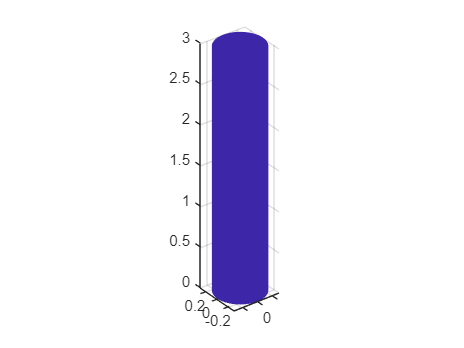

x=0;
y=0;
z=0;
u=3;
v=0;
w=0;

dirarrow3(x,y,z,u,v,w)

function dirarrow3(x,y,z,u,v,w,varargin)

p = inputParser();
p.addParameter('color',[]);
p.parse(varargin{:});

du  = x-u;
dv  = y-v;
dw  = z-w;
nrm = norm([du,dv,dw]);
ahs = .5*nrm;
ahr = .15*nrm;
bdr = .1*nrm;
n=40;
m=2;
theta = (0:n)/n*2*pi;
sintheta = sin(theta); 
sintheta(n+1) = 0;
bdr=[bdr;bdr];
xb = bdr * cos(theta)+x;
yb = bdr * sintheta+y;
zb = z+nrm*(0:m-1)'/(m-1)*ones(1,n+1);


surf(xb,yb,zb,'EdgeColor','none')
axis equal
end